%main主函数
%created by MW
%date: 2023/2/28
%func: Artificial Potential Field（APF） avoiding obstacle

clc;
clear;

## 创建并绘制障碍物

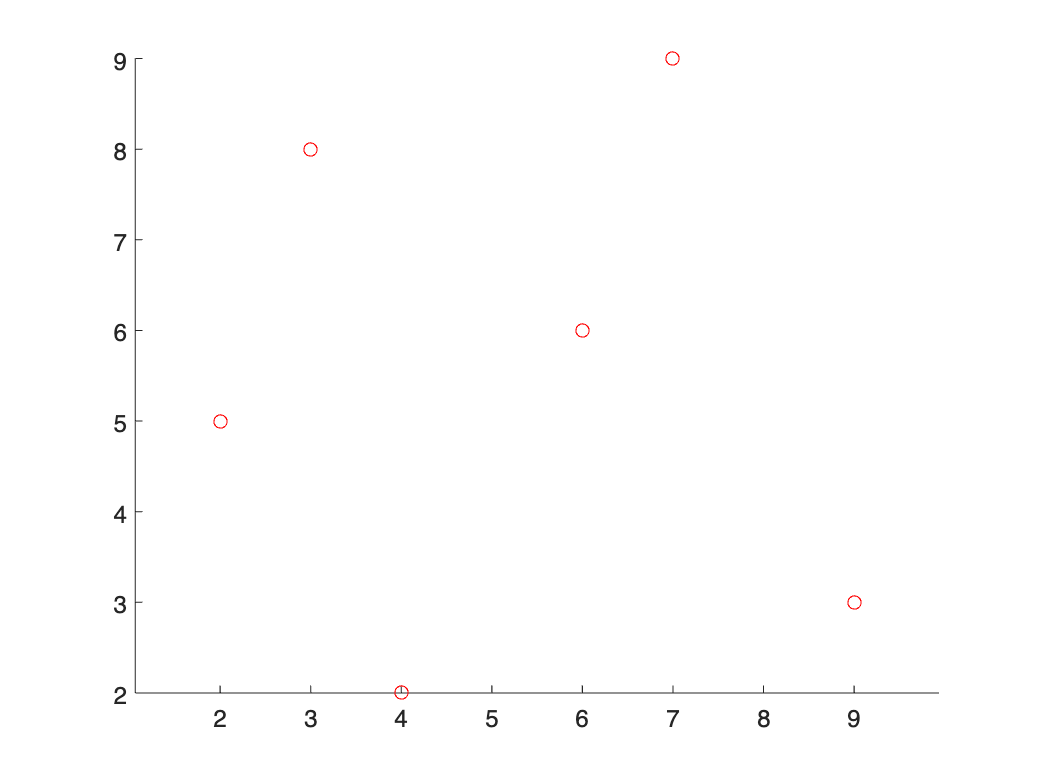

obstacle = [2 5;
    3 8;
    7 9;
    4 2;
    6 6;
    9 3];
figure(1);
scatter(obstacle(:,1),obstacle(:,2),'r')
axis equal;

## 创建并绘制初始位置和目标位置

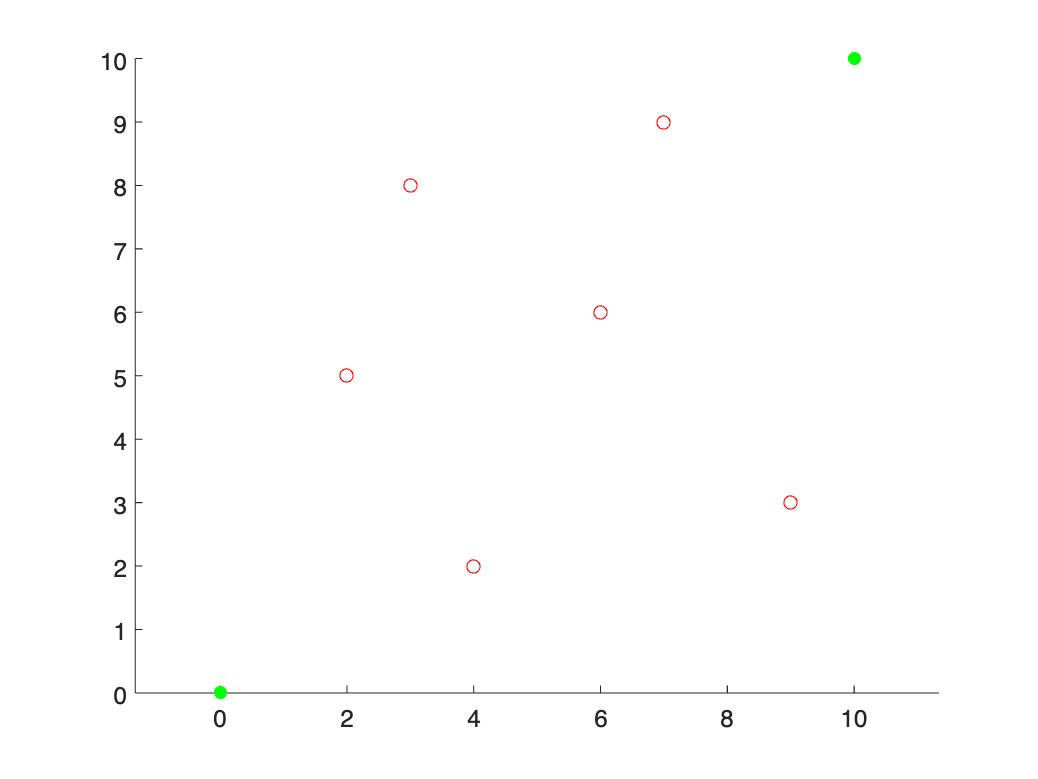

start = [0 0];
goal = [10 10];
hold on;
scatter(start(1),start(2),'filled','g');
scatter(goal(1),goal(2),'filled','g');

## 图片标注

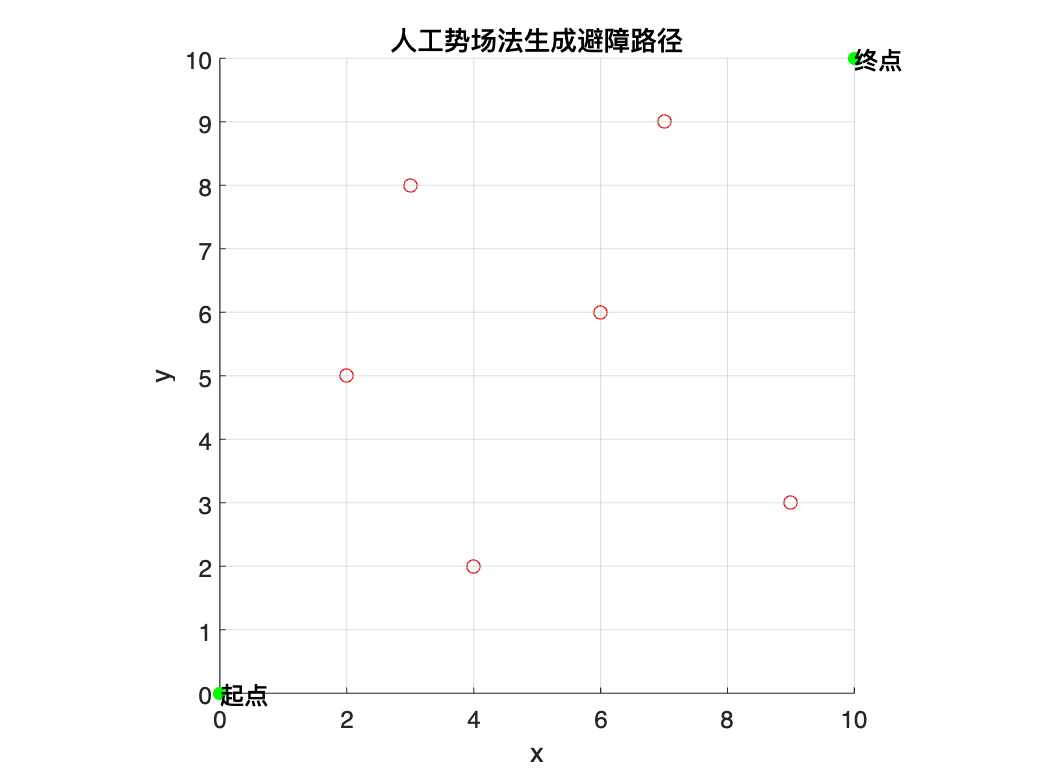

text(start(1),start(2),'起点');
text(goal(1),goal(2),'终点');
grid on;
axis equal;
axis([0 10 0 10]);
xlabel('x');
ylabel('y');
title('人工势场法生成避障路径')

## 生成并绘制避障路径

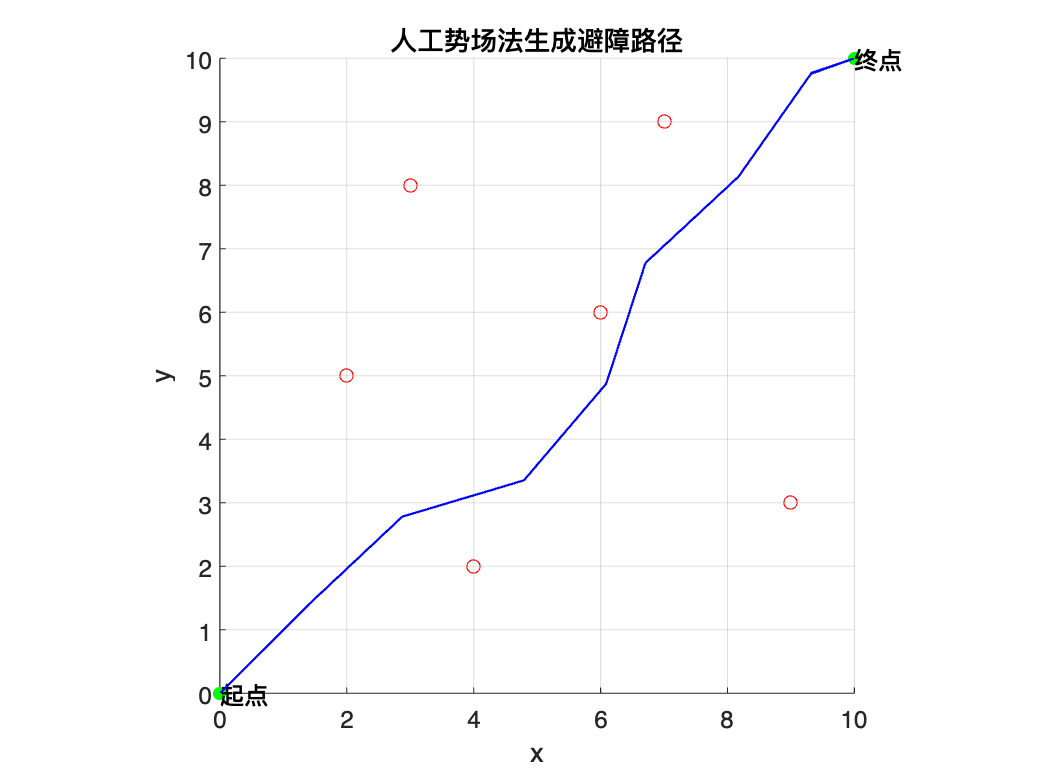

path = APF2D(start, goal, obstacle);
hold on;
plot(path(:,1), path(:,2),'LineWidth',1,'Color','b');